load('test3.mat')
doTraining = false;
outputFolder = 'test2_pcd/';
lidarData = fileDatastore(outputFolder,'ReadFcn',@(x) pcread(x));

Labels = timetable2table(gTruth.LabelData);
boxLabels = Labels(:,"boat");

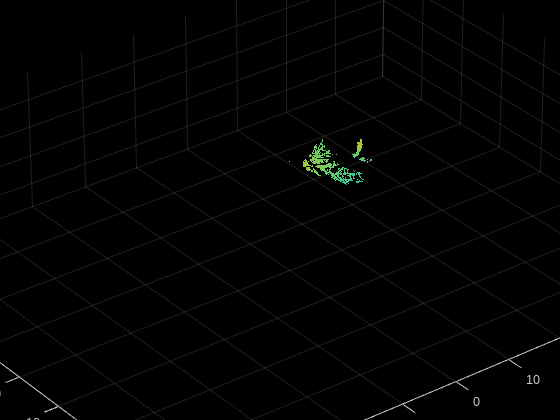

figure
ptCld = read(lidarData);
ax = pcshow(ptCld.Location);
set(ax,'XLim',[-50 50],'YLim',[-40 40]);
zoom(ax,2.5);
axis on;

reset(lidarData);

xMin = 0.0;     % Minimum value along X-axis.
yMin = 0.0;  % Minimum value along Y-axis.
zMin = -50.0;    % Minimum value along Z-axis.
xMax = 120.3;   % Maximum value along X-axis.
yMax = 120.3;   % Maximum value along Y-axis.
zMax = 120.0;     % Maximum value along Z-axis.
xStep = 0.16;   % Resolution along X-axis.
yStep = 0.16;   % Resolution along Y-axis.
dsFactor = 2; % Downsampling factor.

% Calculate the dimensions for the pseudo-image.
Xn = round(((xMax - xMin)/xStep));
Yn = round(((yMax - yMin)/yStep));
Xn

Xn = 752

Yn

Yn = 752

% Define point cloud parameters.
pointCloudRange = [xMin xMax yMin yMax zMin zMax];
voxelSize = [xStep yStep];

[croppedPointCloudObj,processedLabels] = cropFrontViewFromLidarData(lidarData,boxLabels,pointCloudRange);

Processing data 100% complete

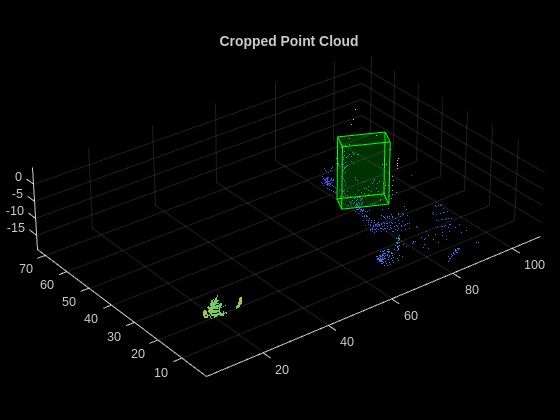

pc = croppedPointCloudObj{1,1};
gtLabelsBoat = processedLabels.boat{1};
% gtLabelsTower = processedLabels.tower(:,1:9);
helperDisplay3DBoxesOverlaidPointCloud(pc.Location,gtLabelsBoat,'green','Cropped Point Cloud');

reset(lidarData);

rng(1);
shuffledIndices = randperm(size(processedLabels,1));
idx = floor(0.7 * length(shuffledIndices));

trainData = croppedPointCloudObj(shuffledIndices(1:idx),:);
testData = croppedPointCloudObj(shuffledIndices(idx+1:end),:);

trainLabels = processedLabels(shuffledIndices(1:idx),:);
testLabels = processedLabels(shuffledIndices(idx+1:end),:);

writeFiles = true;
dataLocation = fullfile(outputFolder,'InputData');
[trainData,trainLabels] = saveptCldToPCD(trainData,trainLabels,...
    dataLocation,writeFiles);

Processing data 100% complete

lds = fileDatastore(dataLocation,'ReadFcn',@(x) pcread(x));

bds = boxLabelDatastore(trainLabels);

cds = combine(lds,bds);

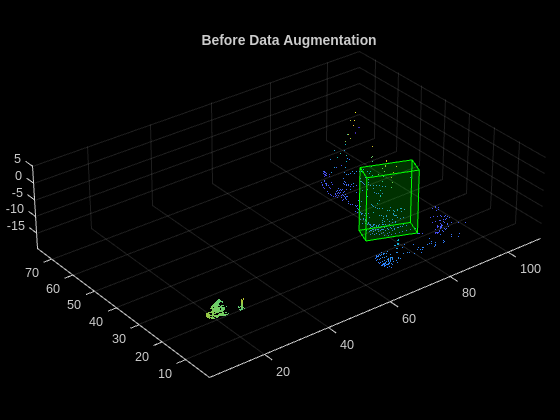

augData = read(cds);
augptCld = augData{1,1};
augLabels = augData{1,2};
augClass = augData{1,3};

labelsCar = augLabels(augClass=='boat',:);

helperDisplay3DBoxesOverlaidPointCloud(augptCld.Location,labelsCar,'green','Before Data Augmentation');

reset(cds);

classNames = {'boat'};
sampleLocation = fullfile(outputFolder,'GTsamples');
[ldsSampled,bdsSampled] = sampleLidarData(cds,classNames,'MinPoints',20,'Verbose',false,'WriteLocation',sampleLocation);

cdsSampled = combine(ldsSampled,bdsSampled);

numObjects = [10];
cdsAugmented = transform(cds,@(x)pcBboxOversample(x,cdsSampled,classNames,numObjects));

%cdsAugmented = transform(cdsAugmented,@(x)augmentData(x));

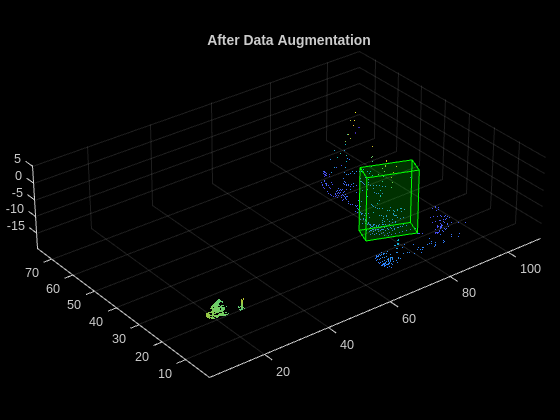

augData = read(cdsAugmented);
augptCld = augData{1,1};
augLabels = augData{1,2};
augClass = augData{1,3};

labelsCar = augLabels(augClass=='boat',:);

helperDisplay3DBoxesOverlaidPointCloud(augptCld.Location,labelsCar,'green','After Data Augmentation');

reset(cdsAugmented);

% Define the number of prominent pillars.
P = 12000; 

% Define the number of points per pillar.
N = 100;   
anchorBoxes = calculateAnchorsPointPillars(trainLabels);
classNames = trainLabels.Properties.VariableNames;

detector = pointPillarsObjectDetector(pointCloudRange,classNames,anchorBoxes,'VoxelSize',voxelSize,'NumPillars',P,'NumPointsPerPillar',N);

executionEnvironment = "auto";
if canUseParallelPool
    dispatchInBackground = true;
else
    dispatchInBackground = false;
end

options = trainingOptions('adam',...
    'Plots',"training-progress",...
    'MaxEpochs',10,...
    'MiniBatchSize',1,...
    'GradientDecayFactor',0.9,...
    'SquaredGradientDecayFactor',0.999,...
    'LearnRateSchedule',"piecewise",...
    'InitialLearnRate',0.0002,...
    'LearnRateDropPeriod',15,...
    'LearnRateDropFactor',0.8,...
    'ExecutionEnvironment',executionEnvironment,...
    'DispatchInBackground',dispatchInBackground,...
    'BatchNormalizationStatistics','moving',...
    'ResetInputNormalization',false,...
    'CheckpointPath',tempdir);

*************************************************************************
Processing data in minibatchqueue....

*************************************************************************
Data processing complete.

*************************************************************************
Training a PointPillars Object Detector for the following object classes:

* boat

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
      1         50         00:01:22       0.0002         2.4772   
      1         100        00:01:48       0.0002         1.7111   
      1         150        00:02:12       0.0002        0.87418   
      1    

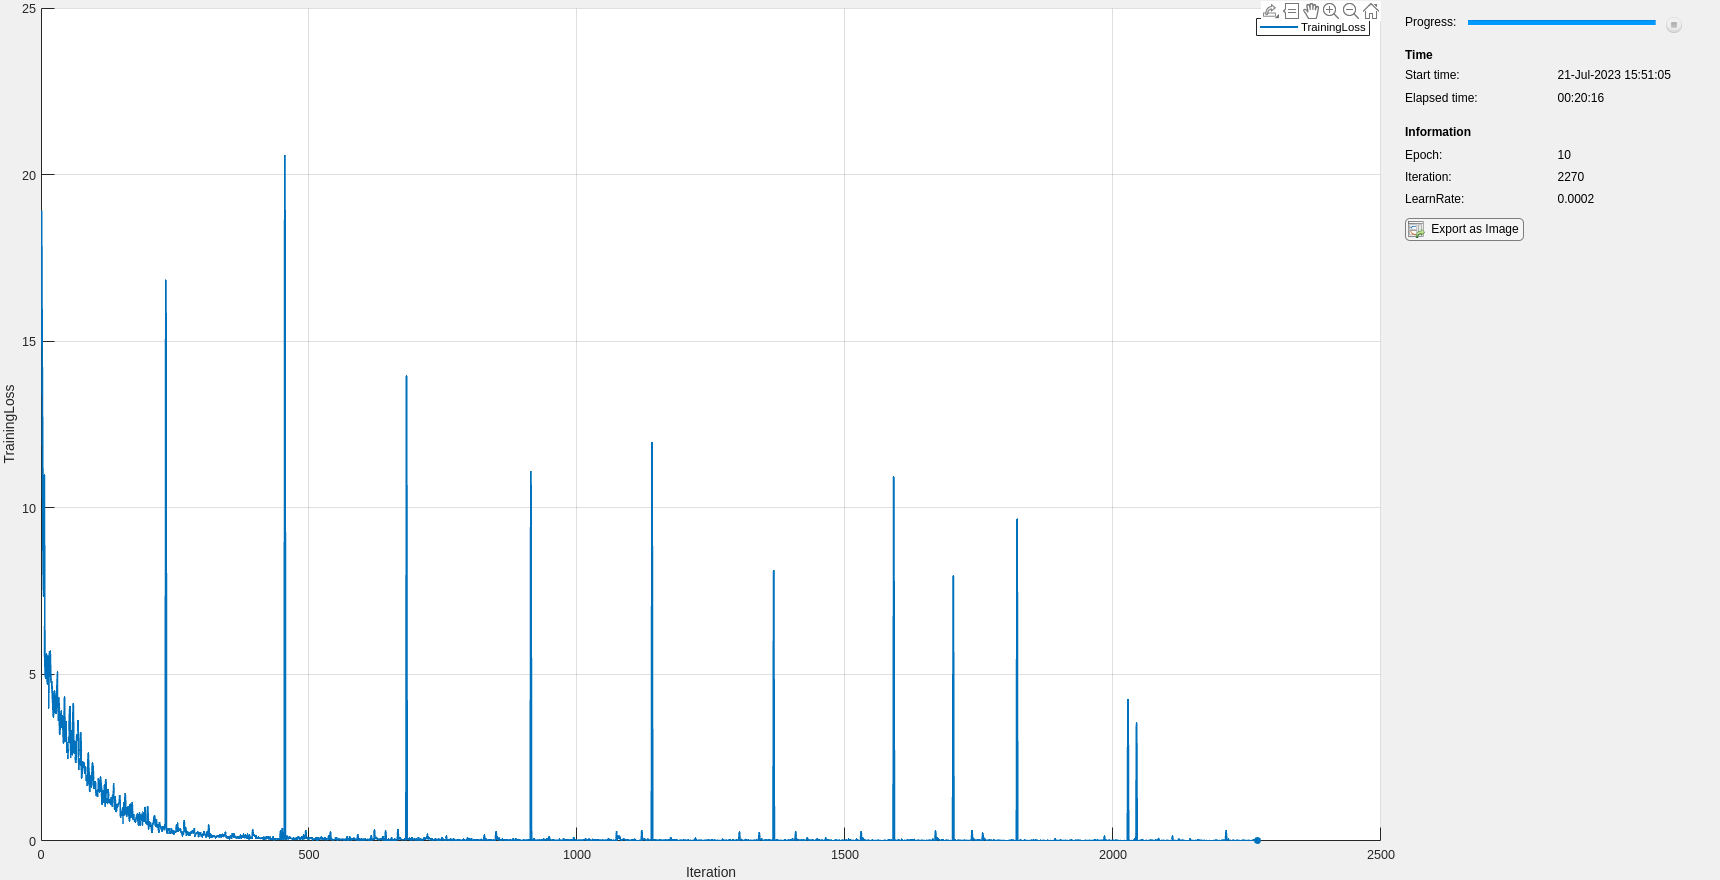

*************************************************************************
Detector training complete.
*************************************************************************



doTraining = true;
if doTraining    
    [detector,info] = trainPointPillarsObjectDetector(cdsAugmented,detector,options);
else
    pretrainedDetector = load('pretrainedPointPillarsDetector.mat','detector');
    detector = pretrainedDetector.detector;
end

ptCloud = testData{46,1};
gtLabels = testLabels(45,:);

% Specify the confidence threshold to use only detections with
% confidence scores above this value.
confidenceThreshold = 0.5;
[box, score, labels] = detect(detector, ptCloud, 'Threshold', confidenceThreshold);
score

score = 2×1 single column vector
    0.7405
    0.5335


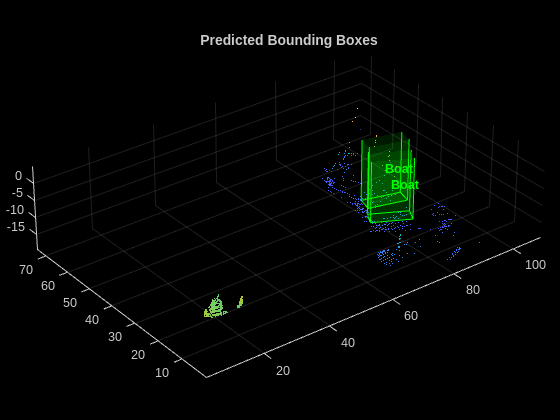

boxlabelsCar = box(labels'=='boat', :);

% Define class names for the predicted boxes
classNames = repmat("Boat", size(boxlabelsCar, 1), 1);

% Display the predictions on the point cloud with class names
helperDisplay3DBoxesOverlaidPointCloud2(ptCloud.Location, boxlabelsCar, classNames, 'green', 'Predicted Bounding Boxes');

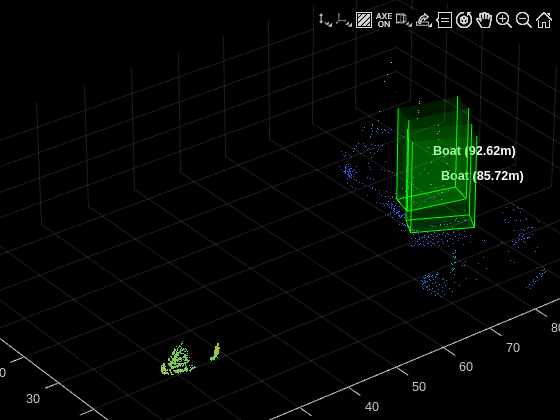

colors = repmat({'white'}, size(boxlabelsCar, 1), 1);
helperDisplay3DBoxesOverlaidPointCloud3(ptCloud.Location, boxlabelsCar, classNames, colors, 'Predicted Bounding Boxes with Distance');

numInputs = 50;

% Generate rotated rectangles from the cuboid labels.
bds = boxLabelDatastore(testLabels(1:numInputs,:));
groundTruthData = transform(bds,@(x)createRotRect(x));

% Set the threshold values.
nmsPositiveIoUThreshold = 0.5;
confidenceThreshold = 0.25;

detectionResults = detect(detector,testData(1:numInputs,:),...
    'Threshold',confidenceThreshold);

% Convert the bounding boxes to rotated rectangles format and calculate
% the evaluation metrics.
for i = 1:height(detectionResults)
    box = detectionResults.Boxes{i};
    detectionResults.Boxes{i} = box(:,[1,2,4,5,9]);
end

metrics = evaluateDetectionAOS(detectionResults,groundTruthData,...
    nmsPositiveIoUThreshold);
disp(metrics(:,1:2))

              AOS        AP   
            _______    _______

    boat    0.10349    0.10356



function helperDisplay3DBoxesOverlaidPointCloud(ptCld,labelsBoat,boatColor,titleForFigure)
% Display the point cloud with different colored bounding boxes for different
% classes.
    figure;
    ax = pcshow(ptCld);
    showShape('cuboid',labelsBoat,'Parent',ax,'Opacity',0.1,...
        'Color',boatColor,'LineWidth',0.5);
    % hold on;
    % showShape('cuboid',labelsTruck,'Parent',ax,'Opacity',0.1,...
    %     'Color',truckColor,'LineWidth',0.5);
    title(titleForFigure);
    zoom(ax,1.5);
end

function helperDisplay3DBoxesOverlaidPointCloud2(ptCld, labelsBoat, classNames, boatColor, titleForFigure)
    % Display the point cloud with different colored bounding boxes for different classes.
    figure;
    ax = pcshow(ptCld);
    showShape('cuboid', labelsBoat, 'Parent', ax, 'Opacity', 0.1, ...
        'Color', boatColor, 'LineWidth', 0.5);
    
    % Display class names on the bounding boxes
    numBoxes = size(labelsBoat, 1);
    for i = 1:numBoxes
        box = labelsBoat(i, :);
        className = classNames{i};
        text(box(1, 1), box(1, 2), box(1, 3), className, ...
            'Color', boatColor, 'FontSize', 10, 'FontWeight', 'bold');
    end
    
    title(titleForFigure);
    zoom(ax, 1.5);
end
function helperDisplay3DBoxesOverlaidPointCloud3(ptCloud, boxes, classNames, colors, titleName)
    figure;
    ax = pcshow(ptCloud);
    title(titleName);
    xlabel('X (m)');
    ylabel('Y (m)');
    zlabel('Z (m)');
    hold on;

    % Display each bounding box with the corresponding class name and distance
    numBoxes = size(boxes, 1);
    for i = 1:numBoxes
        box = boxes(i, :);
        className = classNames{i};
        
        % Calculate the centroid of the bounding box
        centroid = [box(1) + box(4) / 2, box(2) + box(5) / 2, box(3) + box(6) / 2];
        
        % Calculate the distance from the centroid to the origin
        distance = norm(centroid);
        
        % Display the class name and distance on the bounding box
        text(box(1), box(2), box(3), sprintf('%s (%.2fm)', className, distance), ...
            'Color', colors{i}, 'FontSize', 10, 'FontWeight', 'bold');
        
        % Draw the bounding box
        %drawBoundingBox3D(box,colors{i});
    ax = pcshow(ptCloud);
    showShape('cuboid', box, 'Parent', ax, 'Opacity', 0.1, ...
        'Color', 'green', 'LineWidth', 0.5);
    
    % Display class names on the bounding boxes
    % numBoxes = size(box, 1);
    % for i = 1:numBoxes
    %     box = box(i, :);
    %     className = classNames{i};
    %     text(box(1, 1), box(1, 2), box(1, 3), className, ...
    %         'Color', 'green', 'FontSize', 10, 'FontWeight', 'bold');
    %end
    
    %title(titleForFigure);
    zoom(ax, 1.5);
    end

    hold off;
end


